clear;
close all;

% import the constant parameters
run("call_hyperParam.m")

% Number of setpoints - 1 for the drone between hover points
mu = 5;
% number of set
N_tot = 40;

% Number of setpoints for the drone
K_tot = floor(N_tot/mu); % Number of hover points

x = sym('x',[1 N_tot]);
y = sym('y',[1 N_tot]);
x_c = sym('x_c', [1 1]);
y_c = sym('y_c', [1 1]);

d_c(x,y,x_c,y_c) = sqrt(H^2 + (x-x_c).^2 + (y-y_c).^2);
h_n(x,y,x_c,y_c) = alpha_0 * d_c.^(-2);
inner_log(x,y,x_c,y_c) = 1 + P/sigma_0^2 * h_n;
R_n(x,y,x_c,y_c) = B * log2(inner_log);
R_avg(x,y,x_c,y_c) = 1/N_tot * sum(R_n);

### Calculate the Taylor expasion of first order

% gradients with respect to x
R_avg_gradx(x,y,x_c,y_c) = gradient(R_avg, x).';

% gradients with respect to y
R_avg_grady(x,y,x_c,y_c) = gradient(R_avg, y).';

## Simulation parameter

eta = 0.5;

## Simulation Setup

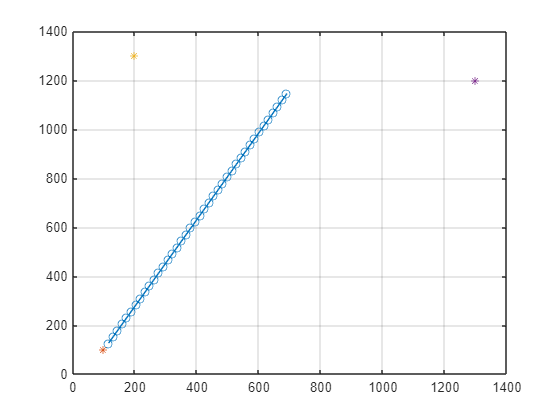

% Basestation
S_s = [100; 100];
% Communication user
S_c = [1.3e3; 1.2e3];
% Sensing target
S_t = [200; 1.3e3];

% target estimation via grid search
S_target_est = S_t + L_x/20*randn(2,1);

% Middle point between communication user und target user
S_mid = (S_c + S_target_est)/2;

% Inital trajectory
[S_traj_init, V_init] = init_trajectory(S_s, N_tot, S_mid, V_str, T_f);
plot_trajectory(S_traj_init, S_s, S_t, S_c)

### Parameter for test:

x_in = S_traj_init(1, :);
y_in = S_traj_init(2, :);
x_c_in = S_c(1);
y_c_in = S_c(2);

S_hover = S_traj_init(:, mu:mu:N_tot);

### Test rate

rate_value_sym = double(subs(R_avg, [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in]))

rate_value_sym = 6.5073e+06

rate_value_cf = compute_rate(S_traj_init, S_c, H, N_tot)

rate_value_cf = 6.5073e+06

% Squared difference
(rate_value_sym - rate_value_cf).^2

ans = 0

### Test for distance to sensing target

% symboliv Math tool Box
derivatex_d_c_sym = double(subs(diag(jacobian(d_c, x)), [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in])).'

derivatex_d_c_sym =    -0.7353   -0.7391   -0.7430   -0.7470   -0.7511   -0.7554   -0.7597   -0.7642   -0.7688   -0.7735   -0.7784   -0.7834   -0.7885   -0.7938   -0.7993   -0.8048   -0.8106   -0.8165   -0.8225   -0.8287   -0.8350   -0.8414   -0.8480   -0.8547   -0.8616   -0.8685   -0.8755   -0.8825   -0.8895   -0.8965   -0.9034   -0.9101   -0.9167   -0.9229   -0.9287   -0.9340   -0.9386   -0.9423   -0.9451   -0.9467


% closed form
d_c_cf = compute_dc(S_traj_init, S_c, H, N_tot);
x_c_diff = (S_traj_init(1,:) - S_c(1));
derivatex_dc_cf = x_c_diff ./ d_c_cf

derivatex_dc_cf =    -0.7353   -0.7391   -0.7430   -0.7470   -0.7511   -0.7554   -0.7597   -0.7642   -0.7688   -0.7735   -0.7784   -0.7834   -0.7885   -0.7938   -0.7993   -0.8048   -0.8106   -0.8165   -0.8225   -0.8287   -0.8350   -0.8414   -0.8480   -0.8547   -0.8616   -0.8685   -0.8755   -0.8825   -0.8895   -0.8965   -0.9034   -0.9101   -0.9167   -0.9229   -0.9287   -0.9340   -0.9386   -0.9423   -0.9451   -0.9467


% MSE of the distance to the sensing target
mean((derivatex_d_c_sym - derivatex_dc_cf).^2)

ans = 3.0815e-33

### Test gradient of the rate function

% get double value of the rate
derivatex_rate_sym = double(subs(gradient(R_avg, x), [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in])).'

derivatex_rate_sym =    32.0753   32.8439   33.6434   34.4757   35.3424   36.2455   37.1870   38.1691   39.1940   40.2642   41.3823   42.5509   43.7729   45.0514   46.3894   47.7904   49.2578   50.7952   52.4063   54.0949   55.8647   57.7198   59.6638   61.7003   63.8327   66.0638   68.3960   70.8307   73.3682   76.0073   78.7451   81.5761   84.4917   87.4799   90.5240   93.6021   96.6863   99.7416  102.7251  105.5861


% closed form gradient
gradientx_rate_cf = compute_gradient_rate_x(S_traj_init, S_c, H, N_tot)

gradientx_rate_cf =    32.0753   32.8439   33.6434   34.4757   35.3424   36.2455   37.1870   38.1691   39.1940   40.2642   41.3823   42.5509   43.7729   45.0514   46.3894   47.7904   49.2578   50.7952   52.4063   54.0949   55.8647   57.7198   59.6638   61.7003   63.8327   66.0638   68.3960   70.8307   73.3682   76.0073   78.7451   81.5761   84.4917   87.4799   90.5240   93.6021   96.6863   99.7416  102.7251  105.5861


% MSE of the distance to the sensing target
mean((derivatex_rate_sym - gradientx_rate_cf).^2)

ans = 2.1205e-28

### Test gradient of the rate function

% get double value of the rate
derivatey_rate_sym = double(subs(gradient(R_avg, y), [x,y,x_c,y_c], [x_in, y_in, x_c_in, y_c_in])).'

derivatey_rate_sym =    29.0615   29.4001   29.7400   30.0805   30.4211   30.7608   31.0988   31.4340   31.7651   32.0907   32.4091   32.7185   33.0167   33.3012   33.5691   33.8173   34.0420   34.2389   34.4032   34.5292   34.6108   34.6406   34.6104   34.5108   34.3313   34.0597   33.6824   33.1842   32.5479   31.7542   30.7818   29.6073   28.2050   26.5474   24.6050   22.3473   19.7431   16.7617   13.3746    9.5568


% closed form gradient
gradienty_rate_cf = compute_gradient_rate_y(S_traj_init, S_c, H, N_tot)

gradienty_rate_cf =    29.0615   29.4001   29.7400   30.0805   30.4211   30.7608   31.0988   31.4340   31.7651   32.0907   32.4091   32.7185   33.0167   33.3012   33.5691   33.8173   34.0420   34.2389   34.4032   34.5292   34.6108   34.6406   34.6104   34.5108   34.3313   34.0597   33.6824   33.1842   32.5479   31.7542   30.7818   29.6073   28.2050   26.5474   24.6050   22.3473   19.7431   16.7617   13.3746    9.5568


% MSE of the distance to the sensing target
mean((derivatey_rate_sym - gradienty_rate_cf).^2)

ans = 5.3169e-29